# Machine Learning - Exercise 2: Regularized Logistic Regression

Instructions

You will need to complete the following functions in this exericse:

%     plotData.m (same as the last in-class excersice)

%     sigmoid.m (same as the last in-class excersice)

%     predict.m (same as the last in-class excersice)

%     costFunctionReg.m

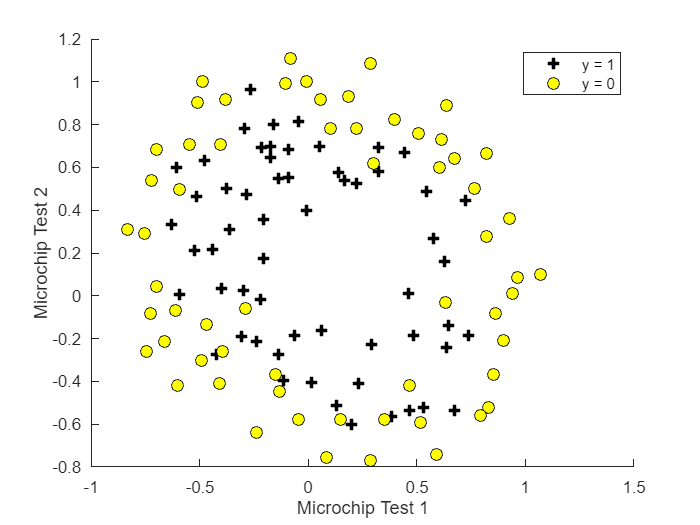


%% Initialization
clear ; close all; clc

%% Load Data
%  The first two columns contains the X values and the third column
%  contains the label (y).

data = load('ex2data2.txt');
X = data(:, [1, 2]); y = data(:, 3);

plotData(X, y);

% Put some labels
hold on;

% Labels and Legend
xlabel('Microchip Test 1')
ylabel('Microchip Test 2')

% Specified in plot order

legend('y = 1', 'y = 0')
hold off;



%% =========== Part 1: Regularized Logistic Regression ============
%  In this part, you are given a dataset with data points that are not
%  linearly separable. However, you would still like to use logistic
%  regression to classify the data points.
%
%  To do so, you introduce more features to use -- in particular, you add
%  polynomial features to our data matrix (similar to polynomial
%  regression).
%

% Add Polynomial Features

% Note that mapFeature also adds a column of ones for us, so the intercept
% term is handled
X = mapFeature(X(:,1), X(:,2));

% Initialize fitting parameters
initial_theta = zeros(size(X, 2), 1);

% Set regularization parameter lambda to 1
lambda = 1;

% Compute and display initial cost and gradient for regularized logistic
% regression
[cost, grad] = costFunctionReg(initial_theta, X, y, lambda);

fprintf('Cost at initial theta (zeros): %f\n', cost);

Cost at initial theta (zeros): 0.693147


fprintf('Expected cost (approx): 0.693\n');

Expected cost (approx): 0.693


fprintf('Gradient at initial theta (zeros) - first five values only:\n');

Gradient at initial theta (zeros) - first five values only:


fprintf(' %f \n', grad(1:5));

 0.008475 
 0.018788 
 0.000078 
 0.050345 
 0.011501 


fprintf('Expected gradients (approx) - first five values only:\n');

Expected gradients (approx) - first five values only:


fprintf(' 0.0085\n 0.0188\n 0.0001\n 0.0503\n 0.0115\n');

 0.0085
 0.0188
 0.0001
 0.0503
 0.0115



fprintf('\nProgram paused. Press enter to continue.\n');


Program paused. Press enter to continue.


pause;


% Compute and display cost and gradient
% with all-ones theta and lambda = 10
test_theta = ones(size(X,2),1);
[cost, grad] = costFunctionReg(test_theta, X, y, 10);

fprintf('\nCost at test theta (with lambda = 10): %f\n', cost);


Cost at test theta (with lambda = 10): 3.206882


fprintf('Expected cost (approx): 3.16\n');

Expected cost (approx): 3.16


fprintf('Gradient at test theta - first five values only:\n');

Gradient at test theta - first five values only:


fprintf(' %f \n', grad(1:5));

 0.430791 
 0.161352 
 0.194796 
 0.226863 
 0.092186 


fprintf('Expected gradients (approx) - first five values only:\n');

Expected gradients (approx) - first five values only:


fprintf(' 0.3460\n 0.1614\n 0.1948\n 0.2269\n 0.0922\n');

 0.3460
 0.1614
 0.1948
 0.2269
 0.0922



fprintf('\nProgram paused. Press enter to continue.\n');


Program paused. Press enter to continue.


pause;

%% ============= Part 2: Regularization and Accuracies =============
%  Optional Exercise:
%  In this part, you will get to try different values of lambda and
%  see how regularization affects the decision coundart
%
%  Try the following values of lambda (0, 1, 10, 100).
%
%  How does the decision boundary change when you vary lambda? How does
%  the training set accuracy vary?
%

% Initialize fitting parameters
initial_theta = zeros(size(X, 2), 1);

% Set regularization parameter lambda to 1 (you should vary this)
lambda = 1;

% Set Options
options = optimset('GradObj', 'on', 'MaxIter', 400);

% Optimize
[theta, J, exit_flag] = ...
	fminunc(@(t)(costFunctionReg(t, X, y, lambda)), initial_theta, options);


Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


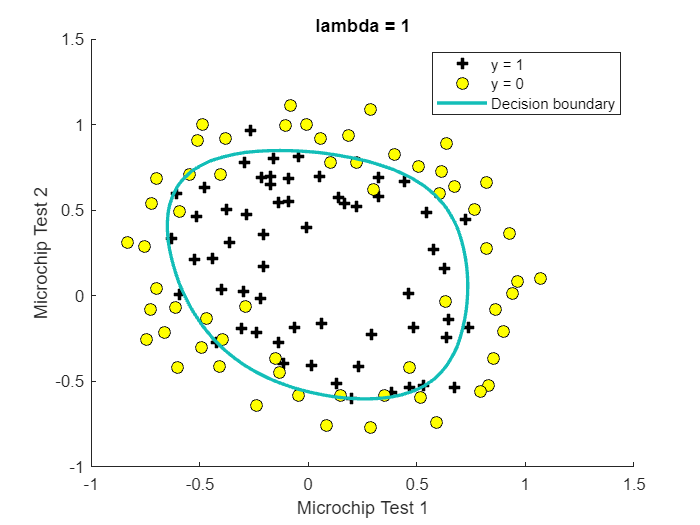


% Plot Boundary
plotDecisionBoundary(theta, X, y);
hold on;
title(sprintf('lambda = %g', lambda))

% Labels and Legend
xlabel('Microchip Test 1')
ylabel('Microchip Test 2')

legend('y = 1', 'y = 0', 'Decision boundary')
hold off;


% Compute accuracy on our training set
p = predict(theta, X);

fprintf('Train Accuracy: %f\n', mean(double(p == y)) * 100);

Train Accuracy: 82.203390


fprintf('Expected accuracy (with lambda = 1): 83.1 (approx)\n');

Expected accuracy (with lambda = 1): 83.1 (approx)


function plotData(X, y)
%PLOTDATA Plots the data points X and y into a new figure 
%   PLOTDATA(x,y) plots the data points with + for the positive examples
%   and o for the negative examples. X is assumed to be a Mx2 matrix.

% Create New Figure
figure; hold on;

% ====================== YOUR CODE HERE ======================
% Instructions: Plot the positive and negative examples on a
%               2D plot, using the option 'k+' for the positive
%               examples and 'ko' for the negative examples.
%
% Find Indices of Positive and Negative Examples
pos = find(y);
neg = find(y==0);

% Plot Examples
plot(X(pos, 1), X(pos, 2), 'k+','LineWidth', 2, ...
'MarkerSize', 7);
plot(X(neg, 1), X(neg, 2), 'ko', 'MarkerFaceColor', 'y', ...
'MarkerSize', 7);






% =========================================================================


hold off;

end

sigmoid/logistic function 

function g = sigmoid(z)
%SIGMOID Compute sigmoid function
%   g = SIGMOID(z) computes the sigmoid of z.

% You need to return the following variables correctly 
g = zeros(size(z));

% ====================== YOUR CODE HERE ======================
% Instructions: Compute the sigmoid of each value of z (z can be a matrix,
%               vector or scalar).

g = 1./(1+exp(-z));



% =============================================================

end

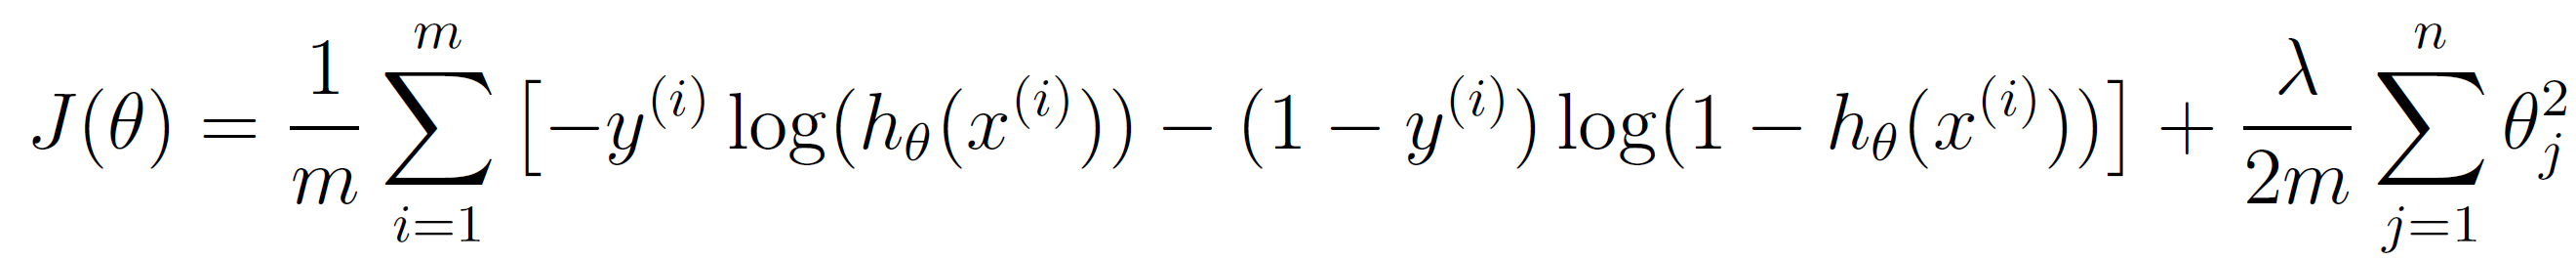

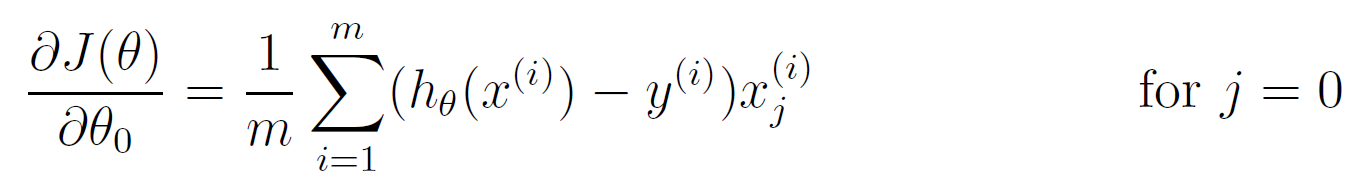

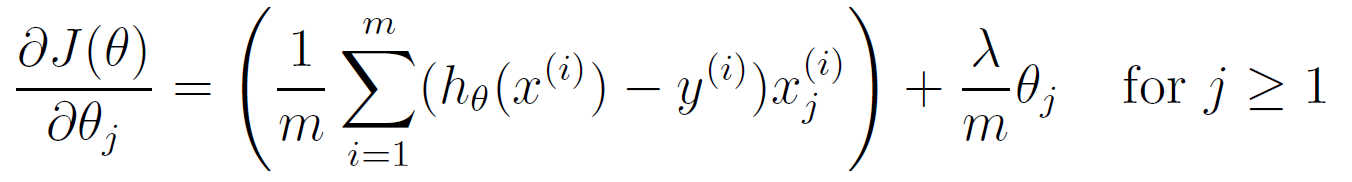

function [J, grad] = costFunctionReg(theta, X, y, lambda)
%COSTFUNCTIONREG Compute cost and gradient for logistic regression with regularization
%   J = COSTFUNCTIONREG(theta, X, y, lambda) computes the cost of using
%   theta as the parameter for regularized logistic regression and the
%   gradient of the cost w.r.t. to the parameters. 

% Initialize some useful values
m = length(y); % number of training examples

% You need to return the following variables correctly 
J = 0;
grad = zeros(size(theta));

% ====================== YOUR CODE HERE ======================
% Instructions: Compute the cost of a particular choice of theta.
%               You should set J to the cost.
%               Compute the partial derivatives and set grad to the partial
%               derivatives of the cost w.r.t. each parameter in theta


h = sigmoid(X*theta);
J = 1/m * (-y'*log(h)-(1-y)'*log(1-h)) + lambda/(2*m)*(theta'*theta);
for j = 1:size(theta)
    grad(j) = 1/m*(h-y)'*X(:, j) + lambda/m*theta(j);
end



% =============================================================

end


h_theta(x)>= 0.5, predict 1, otherwise, predict 0

function p = predict(theta, X)
%PREDICT Predict whether the label is 0 or 1 using learned logistic 
%regression parameters theta

m = size(X, 1); % Number of training examples

% You need to return the following variables correctly
p = zeros(m, 1);

% ====================== YOUR CODE HERE ======================
% Instructions: Complete the following code to make predictions using
%               your learned logistic regression parameters. 
%               You should set p to a vector of 0's and 1's
%

h_theta = sigmoid(X*theta);

p(h_theta>= 0.5) = 1;



% =========================================================================


end



Appendix [DO NOT CHANGE THESE ]

function plotDecisionBoundary(theta, X, y)
%PLOTDECISIONBOUNDARY Plots the data points X and y into a new figure with
%the decision boundary defined by theta
%   PLOTDECISIONBOUNDARY(theta, X,y) plots the data points with + for the 
%   positive examples and o for the negative examples. X is assumed to be 
%   a either 
%   1) Mx3 matrix, where the first column is an all-ones column for the 
%      intercept.
%   2) MxN, N>3 matrix, where the first column is all-ones

% Plot Data
plotData(X(:,2:3), y);
hold on

if size(X, 2) <= 3
    % Only need 2 points to define a line, so choose two endpoints
    plot_x = [min(X(:,2))-2,  max(X(:,2))+2];

    % Calculate the decision boundary line
    plot_y = (-1./theta(3)).*(theta(2).*plot_x + theta(1));

    % Plot, and adjust axes for better viewing
    plot(plot_x, plot_y)
    
    % Legend, specific for the exercise
    legend('Admitted', 'Not admitted', 'Decision Boundary')
    axis([30, 100, 30, 100])
else
    % Here is the grid range
    u = linspace(-1, 1.5, 50);
    v = linspace(-1, 1.5, 50);

    z = zeros(length(u), length(v));
    % Evaluate z = theta*x over the grid
    for i = 1:length(u)
        for j = 1:length(v)
            z(i,j) = mapFeature(u(i), v(j))*theta;
        end
    end
    z = z'; % important to transpose z before calling contour

    % Plot z = 0
    % Notice you need to specify the range [0, 0]
    contour(u, v, z, [0, 0], 'LineWidth', 2)
end
hold off

end


function out = mapFeature(X1, X2)
% MAPFEATURE Feature mapping function to polynomial features
%
%   MAPFEATURE(X1, X2) maps the two input features
%   to quadratic features used in the regularization exercise.
%
%   Returns a new feature array with more features, comprising of 
%   X1, X2, X1.^2, X2.^2, X1*X2, X1*X2.^2, etc..
%
%   Inputs X1, X2 must be the same size
%

degree = 6;
out = ones(size(X1(:,1)));
for i = 1:degree
    for j = 0:i
        out(:, end+1) = (X1.^(i-j)).*(X2.^j);
    end
end

end
